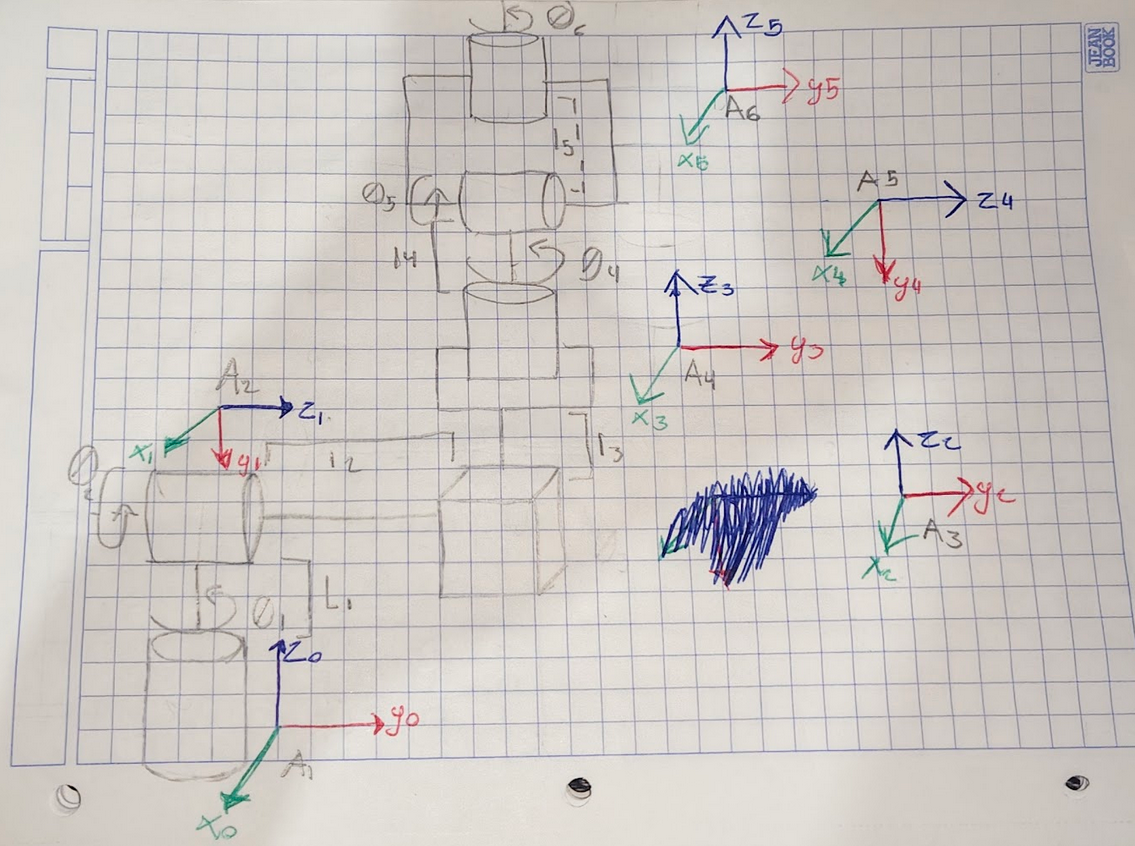

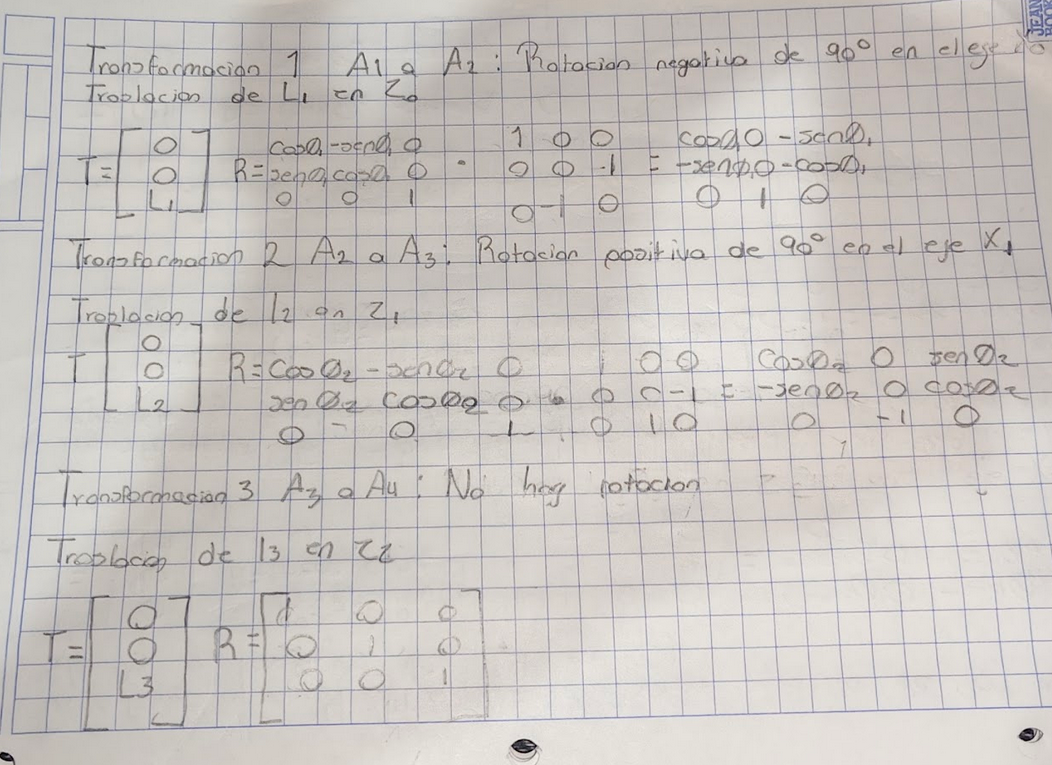

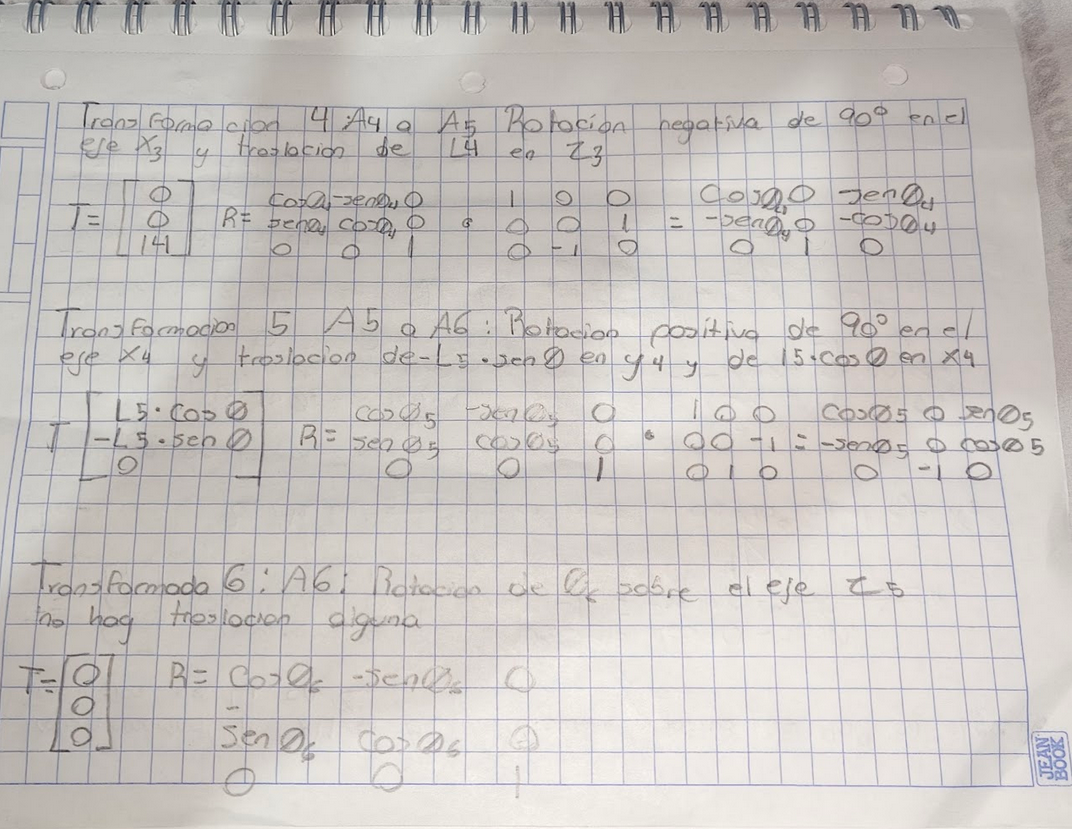

**Definición de Parámetros y Variables**

Consiste en definir las coordenadas generalizadas q y los parámetros físicos del robot

Coordenadas Articulares: Q=[θ1,θ2,θ3,θ4,θ5,θ6]T

Configuración: Se define un vector `RP` donde `0` representa una junta de revolución y `1` una prismática. En este modelo: `RP = [0 0 1 0 0 0]`.

%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t   %Angulos de cada articulación
syms th1p(t) th2p(t) th3p(t) th4p(t) th5p(t) th6p(t)   %Velocidades de cada articulación
syms th1pp(t) th2pp(t) th3pp(t) th4pp(t) th5pp(t) th6pp(t) %Aceleraciones de cada articulación
syms m1 m2 m3 m4 m5 m6 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 Ixx4 Iyy4 Izz4 Ixx5 Iyy5 Izz5 Ixx6 Iyy6 Izz6 %Masas y matrices de Inercia
syms l1 l2 l3 l4 l5 l6 lc1 lc2 lc3 lc4 lc5 lc6 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

 %Creamos el vector de coordenadas articulares
  Q= [th1; th2; th3; th4; th5; th6];
 %disp('Coordenadas generalizadas');
 %pretty (Q);
 
 %Creamos el vector de velocidades articulares
  Qp= [th1p; th2p; th3p; th4p; th5p; th6p];
 %disp('Velocidades generalizadas');
 %pretty (Qp);
 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp; th2pp; th3pp; th4pp; th5pp; th6pp];
 %disp('Aceleraciones generalizadas');
 %pretty (Qpp);

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 1 0 0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

**Cinemática Directa**

La cinemática directa define la posición y orientación del efector final respecto a la base. utilizamos matrices de transformación homogénea local Ai y global Ti.Matrices de Transformación

Donde:

Ri: Matriz de rotación.

Pi: Vector de traslación.        

La matriz global Ti se obtiene mediante el producto acumulado:

Ti=A1⋅A2⋅⋯⋅Ai

%Articulación 1 
P(:,:,1) = [0; 0; l1];
R(:,:,1) = [cos(th1), -sin(th1), 0; sin(th1), cos(th1), 0; 0, 0, 1] * [1, 0, 0; 0, 0, 1; 0, -1, 0];

%Articulación 2
P(:,:,2) = [0; 0; l2];
R(:,:,2) = [cos(th2), -sin(th2), 0; sin(th2), cos(th2), 0; 0, 0, 1] * [1, 0, 0; 0, 0, -1; 0, 1, 0];

%Articulación 3 (prismático) 
P(:,:,3) = [0; 0; l3 + th3];
R(:,:,3) = [1, 0, 0; 0, 1, 0; 0, 0, 1];

%Articulación 4
P(:,:,4) = [0; 0; l4];
R(:,:,4) = [cos(th4), -sin(th4), 0; sin(th4), cos(th4), 0; 0, 0, 1] * [1, 0, 0; 0, 0, 1; 0, -1, 0];

%Articulación 5
P(:,:,5) = [l5*cos(th5); -l5*sin(th5); 0];
R(:,:,5) = [cos(th5), -sin(th5), 0; sin(th5), cos(th5), 0; 0, 0, 1] * [1, 0, 0; 0, 0, -1; 0, 1, 0];

%Articulación 6
P(:,:,6) = [0; 0; 0];
R(:,:,6) = [cos(th6), -sin(th6), 0; sin(th6), cos(th6), 0; 0, 0, 1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

**Cinemática Diferencial (Jacobianos)**

La cinemática diferencial relaciona las velocidades articulares Qp con las velocidades lineales v y angulares ω de cada eslabón.El Jacobiano Analítico

Para cada eslabón i, calculamos el Jacobiano lineal (Jv) y angular (Jw):

Si la junta es de revolución (RP=0):Jv,k=Zk−1×(pi−pk−1), Jw,k=Zk−1

Si la junta es prismática (RP=1):Jv,k=Zk−1, Jw,k=0

Las velocidades se obtienen como:

Vi=Jv,i⋅Qp,       Wi=Jw,i⋅Qp

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%CALCULAMOS LAS VELOCIDADES PARA CADA ESLABÓN%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Qp=Qp(t); % Evaluamos Qp para usarlo en las multiplicaciones

%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 6  %%%%%%%%%%
Jv_a6(:,6)=PO(:,:,6);
Jw_a6(:,6)=PO(:,:,6);

for k= 1:6
    if RP(k)==0 
        try
            Jv_a6(:,k)= cross(RO(:,3,k-1), PO(:,:,6)-PO(:,:,k-1));
            Jw_a6(:,k)= RO(:,3,k-1);
        catch
            Jv_a6(:,k)= cross([0,0,1], PO(:,:,6));
            Jw_a6(:,k)=[0,0,1];
         end
     else
        try
            Jv_a6(:,k)= RO(:,3,k-1);
        catch
            Jv_a6(:,k)=[0,0,1];
        end
            Jw_a6(:,k)=[0,0,0];
     end
 end    

Jv_a6= simplify (Jv_a6);
Jw_a6= simplify (Jw_a6);

Jac6= [Jv_a6; Jw_a6];
Jacobiano6= simplify(Jac6);

 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6


V6=simplify (Jv_a6*Qp(1:6));
pretty(V6)

/ cos(th1(t)) th2p(t) #1 - th1p(t) (l2 cos(th1(t)) + l4 sin(th1(t)) sin(th2(t)) + sin(th1(t)) sin(th2(t)) (l3 + th3(t)) + l5 cos(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + l5 sin(th1(t)) sin(th2(t)) sin(th5(t))) - th5p(t) (l5 cos(th1(t)) cos(th5(t)) sin(th2(t)) + l5 sin(th1(t)) sin(th4(t)) sin(th5(t)) - l5 cos(th1(t)) cos(th2(t)) cos(th4(t)) sin(th5(t))) + cos(th1(t)) sin(th2(t)) th3p(t) - l5 cos(th5(t)) th4p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      


 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 6');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 6


W6=simplify (Jw_a6*Qp(1:6));
pretty(W6)

/ cos(th1(t)) sin(th2(t)) th4p(t) - th6p(t) (sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - cos(th1(t)) cos(th5(t)) sin(th2(t))) - sin(th1(t)) th2p(t) - th5p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                                                                                                                                               |
| th5p(t) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) + th6p(t) (sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + cos(th5(t)) sin(th1(t)) sin(th2(t))) + cos(th1(t)) th2p(t) + sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                                                                                                                 


%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 5  %%%%%%%%%%
Jv_a5(:,5)=PO(:,:,5);
Jw_a5(:,5)=PO(:,:,5);

for k= 1:5
    if RP(k)==0 
        try
            Jv_a5(:,k)= cross(RO(:,3,k-1), PO(:,:,5)-PO(:,:,k-1));
            Jw_a5(:,k)= RO(:,3,k-1);
        catch
            Jv_a5(:,k)= cross([0,0,1], PO(:,:,5));
            Jw_a5(:,k)=[0,0,1];
         end
     else
        try
            Jv_a5(:,k)= RO(:,3,k-1);
        catch
            Jv_a5(:,k)=[0,0,1];
        end
            Jw_a5(:,k)=[0,0,0];
     end
 end    

Jv_a5= simplify (Jv_a5);
Jw_a5= simplify (Jw_a5);

Jac5= [Jv_a5; Jw_a5];
Jacobiano5= simplify(Jac5);

 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 5');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 5


V5=simplify (Jv_a5*Qp(1:5));
pretty(V5)

/ cos(th1(t)) th2p(t) #1 - th1p(t) (l2 cos(th1(t)) + l4 sin(th1(t)) sin(th2(t)) + sin(th1(t)) sin(th2(t)) (l3 + th3(t)) + l5 cos(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + l5 sin(th1(t)) sin(th2(t)) sin(th5(t))) - th5p(t) (l5 cos(th1(t)) cos(th5(t)) sin(th2(t)) + l5 sin(th1(t)) sin(th4(t)) sin(th5(t)) - l5 cos(th1(t)) cos(th2(t)) cos(th4(t)) sin(th5(t))) + cos(th1(t)) sin(th2(t)) th3p(t) - l5 cos(th5(t)) th4p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      


 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 5');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 5


W5=simplify (Jw_a5*Qp(1:5));
pretty(W5)

/ cos(th1(t)) sin(th2(t)) th4p(t) - sin(th1(t)) th2p(t) - th5p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                 |
| th5p(t) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) + cos(th1(t)) th2p(t) + sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                 |
\                                 th1p(t) + cos(th2(t)) th4p(t) + sin(th2(t)) sin(th4(t)) th5p(t)                                 /




%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 4  %%%%%%%%%%
Jv_a4(:,4)=PO(:,:,4);
Jw_a4(:,4)=PO(:,:,4);

for k= 1:4
    if RP(k)==0 
        try
            Jv_a4(:,k)= cross(RO(:,3,k-1), PO(:,:,4)-PO(:,:,k-1));
            Jw_a4(:,k)= RO(:,3,k-1);
        catch
            Jv_a4(:,k)= cross([0,0,1], PO(:,:,4));
            Jw_a4(:,k)=[0,0,1];
         end
     else
        try
            Jv_a4(:,k)= RO(:,3,k-1);
        catch
            Jv_a4(:,k)=[0,0,1];
        end
            Jw_a4(:,k)=[0,0,0];
     end
 end    

Jv_a4= simplify (Jv_a4);
Jw_a4= simplify (Jw_a4);

Jac4= [Jv_a4; Jw_a4];
Jacobiano4= simplify(Jac4);

 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 4');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 4


V4=simplify (Jv_a4*Qp(1:4));
pretty(V4)

/ cos(th1(t)) sin(th2(t)) th3p(t) - th1p(t) (l2 cos(th1(t)) + l4 sin(th1(t)) sin(th2(t)) + sin(th1(t)) sin(th2(t)) (l3 + th3(t))) + cos(th1(t)) cos(th2(t)) th2p(t) #1 \
|                                                                                                                                                                      |
| th1p(t) (l4 cos(th1(t)) sin(th2(t)) - l2 sin(th1(t)) + cos(th1(t)) sin(th2(t)) (l3 + th3(t))) + sin(th1(t)) sin(th2(t)) th3p(t) + cos(th2(t)) sin(th1(t)) th2p(t) #1 |
|                                                                                                                                                                      |
\                                                             cos(th2(t)) th3p(t) - sin(th2(t)) th2p(t) #1                                                             /

where

   #1 == l3 + l4 + th3(t)





 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 4');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 4


W4=simplify (Jw_a4*Qp(1:4));
pretty(W4)

/ cos(th1(t)) sin(th2(t)) th4p(t) - sin(th1(t)) th2p(t) \
|                                                       |
| cos(th1(t)) th2p(t) + sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                       |
\             th1p(t) + cos(th2(t)) th4p(t)             /




%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 3  %%%%%%%%%%
Jv_a3(:,3)=PO(:,:,3);
Jw_a3(:,3)=PO(:,:,3);

for k= 1:3
    if RP(k)==0 
        try
            Jv_a3(:,k)= cross(RO(:,3,k-1), PO(:,:,3)-PO(:,:,k-1));
            Jw_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)= cross([0,0,1], PO(:,:,3));
            Jw_a3(:,k)=[0,0,1];
         end
     else
        try
            Jv_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)=[0,0,1];
        end
            Jw_a3(:,k)=[0,0,0];
     end
 end    

Jv_a3= simplify (Jv_a3);
Jw_a3= simplify (Jw_a3);

Jac3= [Jv_a3; Jw_a3];
Jacobiano3= simplify(Jac3);

 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3


V3=simplify (Jv_a3*Qp(1:3));
pretty(V3)

/ cos(th1(t)) sin(th2(t)) th3p(t) - th1p(t) (l2 cos(th1(t)) + sin(th1(t)) sin(th2(t)) (l3 + th3(t))) + cos(th1(t)) cos(th2(t)) th2p(t) (l3 + th3(t)) \
|                                                                                                                                                    |
| sin(th1(t)) sin(th2(t)) th3p(t) - th1p(t) (l2 sin(th1(t)) - cos(th1(t)) sin(th2(t)) (l3 + th3(t))) + cos(th2(t)) sin(th1(t)) th2p(t) (l3 + th3(t)) |
|                                                                                                                                                    |
\                                               cos(th2(t)) th3p(t) - sin(th2(t)) th2p(t) (l3 + th3(t))                                              /




 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3


W3=simplify (Jw_a3*Qp(1:3));
pretty(W3)

/ -sin(th1(t)) th2p(t) \
|                      |
|  cos(th1(t)) th2p(t) |
|                      |
\        th1p(t)       /




%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 2  %%%%%%%%%%
Jv_a2(:,2)=PO(:,:,2);
Jw_a2(:,2)=PO(:,:,2);

for k= 1:2
    if RP(k)==0 
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,2)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,2));
            Jw_a2(:,k)=[0,0,1];
         end
     else
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);

Jac2= [Jv_a2; Jw_a2];
Jacobiano2= simplify(Jac2);

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2


V2=simplify (Jv_a2*Qp(1:2));  
pretty(V2)

/ -l2 cos(th1(t)) th1p(t) \
|                         |
| -l2 sin(th1(t)) th1p(t) |
|                         |
\            0            /



 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2


W2=simplify (Jw_a2*Qp(1:2));
pretty(W2)

/ -sin(th1(t)) th2p(t) \
|                      |
|  cos(th1(t)) th2p(t) |
|                      |
\        th1p(t)       /




%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 1  %%%%%%%%%%
Jv_a1(:,1)=PO(:,:,1);
Jw_a1(:,1)=PO(:,:,1);

for k= 1:1
    if RP(k)==0 
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,1));
            Jw_a1(:,k)=[0,0,1];
         end
     else
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);

Jac1= [Jv_a1; Jw_a1];
Jacobiano1= simplify(Jac1);

 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


V1=simplify (Jv_a1*Qp(1:1));
pretty(V1)

/ 0 \
|   |
| 0 |
|   |
\ 0 /



 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify (Jw_a1*Qp(1:1));
pretty(W1)

/    0    \
|         |
|    0    |
|         |
\ th1p(t) /



**Análisis Energético**

Para obtener el modelo dinámico, es necesario calcular la energía total del sistema (H=K+U).

Energía Cinética (K) donde la energía cinética de cada eslabón considera la traslación del centro de masa (lc) y la rotación:

Ki=1/2mi⋅Vci^2+1/2ωi^T⋅Ii⋅ωi

Donde Vci es la velocidad en el centro de masa del eslabón.

Energía Potencial (U) la cual depende de la altura h de los centros de masa respecto al plano de referencia y la gravedad g:

Ui=mi⋅g⋅hi

%Energía Cinética

 P01=subs(P(:,:,1)/2, l1, lc1);
 P12=subs(P(:,:,2)/2, l2, lc2);
 P23=subs(P(:,:,3)/2, l3, lc3);
 P34=subs(P(:,:,4)/2, l4, lc4);
 P45=subs(P(:,:,5)/2, l5, lc5);
 P56=subs(P(:,:,6)/2, l6, lc6);

%Creamos matrices de inercia para cada eslabón
I1=[Ixx1 0 0; 0 Iyy1 0; 0 0 Izz1];
I2=[Ixx2 0 0; 0 Iyy2 0; 0 0 Izz2];
I3=[Ixx3 0 0; 0 Iyy3 0; 0 0 Izz3];
I4=[Ixx4 0 0; 0 Iyy4 0; 0 0 Izz4];
I5=[Ixx5 0 0; 0 Iyy5 0; 0 0 Izz5];
I6=[Ixx6 0 0; 0 Iyy6 0; 0 0 Izz6];

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

              2
Izz1 |th1p(t)|
---------------
       2




%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K2= simplify (K2);
pretty (K2);

                                                                           __                        __
Izz2 #7   Iyy2 #6 cos(th1(t)) #4   Ixx2 #6 sin(th1(t)) #3   cos(th1(t)) #4 m2 #5 #1   sin(th1(t)) #3 m2 #5 #1
------- + ---------------------- + ---------------------- - ----------------------- - -----------------------
   2                 2                        2                        #2                        #2

where

                      lc2 th2p(t)
   #1 == l2 th1p(t) - -----------
                           2

   #2 == 4 l2 lc2 th1p(t) th2p(t)

             ______
   #3 == sin(th1(t))

             ______
   #4 == cos(th1(t))

                    2                        2
   #5 == l2 #6 |lc2|  th1p(t) - 2 lc2 #7 |l2|  th2p(t)

                  2
   #6 == |th2p(t)|

                  2
   #7 == |th1p(t)|





%Eslabón 3
V3_Total= V3+cross(W3,P23);
K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W3)'*(I3*W3);
disp('Energía Cinética en el Eslabón 3');

Energía Cinética en el Eslabón 3


K3= simplify (K3);
pretty (K3);

__                                                            _______      _______          __                                                                                                                                                                                _______         _______     __               _______         _______             __  _______         _______     __               _______         _______                                                                                                                                                                                                _______                _______                               _______
m3 (cos(th2(t)) th3p(t) - sin(th2(t)) th2p(t) (l3 + th3(t))) (th3p(t) #6 - th2p(t) #4 #3)   m3 (cos(th1(t)) th2p(t) #7 - th1p(t) (l2 cos(th1(t)) + sin(th1(t)) sin(th2(t)) (l3 + th3(t))) + cos(th1(t)) sin(th2(t)) th3p(t) + cos(th1(t)) cos(th2(t)) th2p(t) (l3 + th3(t))) (th3p(t) #2 #4 - th1p(t) (#2 l2 + #1 #4 #3) + t


%Eslabón 4
V4_Total= V4+cross(W4,P34);
K4= (1/2*m4*(V4_Total))'*((V4_Total)) + (1/2*W4)'*(I4*W4);
disp('Energía Cinética en el Eslabón 4');

Energía Cinética en el Eslabón 4


K4= simplify (K4);
pretty (K4);

                                                                                                                                                                                     / ___                                                                                              \                                                                                                                                                                                        / ___                                                                                               \
__ / lc4 #2                                                                                                                                                                        \ | lc4 (#9 + #8)   _______      __                        __    _______           _______           |   __ / lc4 #1                                                                                                                                          


%Eslabón 5
V5_Total= V5+cross(W5,P45);
K5= (1/2*m5*(V5_Total))'*((V5_Total)) + (1/2*W5)'*(I5*W5);
disp('Energía Cinética en el Eslabón 5');

Energía Cinética en el Eslabón 5


K5= simplify (K5);
pretty (K5);

                                     /                                                                                          ___                                                             ___                                          \                                                                                                                                                                                                                                                                                                                                                                                                      /                                                                                                                                                                                                         ___                         \                                                                                                                                             


%Eslabón 6
V6_Total= V6+cross(W6,P56);
K6= (1/2*m6*(V6_Total))'*((V6_Total)) + (1/2*W6)'*(I6*W6);
disp('Energía Cinética en el Eslabón 6');

Energía Cinética en el Eslabón 6


K6= simplify (K6);
pretty (K6);

                                                                                           / _______   _______                           _______       _______         \                                                                                                                                              / _______                           _______       _______       _______         \                                                                                                                                              / _______      _______       _______                           _______         \   __  _______  ______           __       __           __               __    _______       _______ __                           _______             __                                                                                                                                                                                                                                         __ 


K_Total= simplify (K1+K2+K3+K4+K5+K6);
disp('Energía Cinética Total');

Energía Cinética Total


pretty (K_Total);

                                                                                                                                                   / ___                                                                                      \                                                                                                                                                                       / ___                                                                                      \      /                 ___                               ___                         \                                                                                                                                                                                                                                                                                                                                                                                                                               


%Energia Potencial  p=mgh

 h1= P01(3); 
 h2= P12(2); 
 h3= P23(3); 
 h4= P34(3); 
 h5= P45(2); 
 h6= P56(3); 

 U1=m1*g*h1

$$U1 = \frac{g\,{\mathrm{lc}}_{1}\,m_{1}}{2}$$

 U2=m2*g*h2

$$U2 = 0$$

 U3=m3*g*h3

$$U3 = g\,m_{3}\,\left(\frac{{\mathrm{lc}}_{3}}{2}+\frac{{\mathrm{th}}_{3}\left(t\right)}{2}\right)$$

 U4=m4*g*h4

$$U4 = \frac{g\,{\mathrm{lc}}_{4}\,m_{4}}{2}$$

 U5=m5*g*h5

$$U5 = -\frac{g\,{\mathrm{lc}}_{5}\,m_{5}\,\sin\left({\mathrm{th}}_{5}\left(t\right)\right)}{2}$$

 U6=m6*g*h6

$$U6 = 0$$


 %Calculamos la energía potencial total
 U_Total= U1 + U2 + U3 + U4 + U5 + U6;

**El Lagrangiano (L)**

El Lagrangiano es la función base para obtener las ecuaciones de movimiento de Euler-Lagrange. Se define como la diferencia entre la energía cinética total y la energía potencial total:

L=Ktotal−Utotal

 %Obtenemos el Lagrangiano
 Lagrangiano= simplify (K_Total-U_Total);
 pretty (Lagrangiano);

                                                                                                                                                   / ___                                                                                      \                                                                                                                                                                       / ___                                                                                      \      /                 ___                               ___                         \                                                                                                                                                                                                                                                                                                                                                                                                                               


%Modelo de Energía
 H= simplify (K_Total+U_Total);
 pretty (H)

                                                                                                                                                   / ___                                                                                      \                                                                                                                                                                       / ___                                                                                      \      /                 ___                               ___                         \                                                                                                                                                                                                                                                                                                                                                                                                                               